%% SCRIPT FOR TESTING LIGHT PROPAGATION THROUGH BRAGG WITH GLASS
% -------------------------------------------------------------------------
%% GENERAL INPUT DATA
% -------------------------------------------------------------------------
lam = linspace(350, 1200, 851);
Bragg = repmat(["SiO2_Fraunhofer", "ZrO2_Fraunhofer"],1,4);
Bragg2 = repmat(["ZrO2_Fraunhofer", "SiO2_Fraunhofer"],1,1);
matPSC = [Bragg,"plain",Bragg2];
dgls = 2e6; dair = 2e6; dEVA = 2e6; dAZO = 5; dARC = 61.8;
incoh = 1e3; % incoherent layer is 1000nm thickness
theta = 0;
dBragg = [121.1546,6.122398,3.296342,12.20901,45.83533,22.49243,51.37742,11.38405];
dBragg2=[1.5,57.69828]

dBragg2 =     1.5000   57.6983


initialBragg = [dBragg, dBragg2];
data = readmatrix('C:\Users\Owner\Desktop\plainBorosil.csv');
% -------------------------------------------------------------------------
% DSM glass EVA PV
% -------------------------------------------------------------------------
materials = ["plain","air","const=2.4254","mSi"];
d = [dair,dARC];
stack = set_stack(materials, d, lam, theta, incoh);
[~, T_DSM_air_PV, ~] = ATR1D(stack);
load("Covestro.mat");
DSM_lam = interp1(DSM(:,1), DSM(:,2), lam, 'spline')';
T_DSM_air_PV = T_DSM_air_PV.sp .* DSM_lam;
Jsc_DSM_air_PV = get_electric(lam, T_DSM_air_PV).jsc;

% -------------------------------------------------------------------------
% GENETIC ALGORITHM TO OPTIMIZE BRAGG LAYER THICKNESSES
% -------------------------------------------------------------------------
nBraggLayers = 10; % Total number of layers to be optimized, 8 on each side
lb = ones(1, nBraggLayers) * 0;
ub = ones(1, nBraggLayers) * 250;
options = optimoptions('ga', 'PopulationSize', 1, 'MaxGenerations', 1, 'Display', 'iter', 'UseParallel', true, 'InitialPopulationMatrix', initialBragg);
[x, fval] = ga(@calculateJsc, nBraggLayers, [], [], [], [], lb, ub, [], options);


Single objective optimization:
10 Variables

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1                2          -32.32          -32.32        0
ga stopped because it exceeded options.MaxGenerations.



% Split the results for each side
dBragg_optimized_side1 = x(1:8); % Optimized thicknesses for the first side
dBragg_optimized_side2 = x(9:end); % Optimized thicknesses for the second side
disp(['Optimal Bragg layer thicknesses: ', num2str(x)]);

Optimal Bragg layer thicknesses: 121.1546      6.122398      3.296342      12.20901      45.83533      22.49243      51.37742      11.38405           1.5      57.69828


disp(['Maximized Jsc: ', num2str(-fval)]);

Maximized Jsc: 32.3182


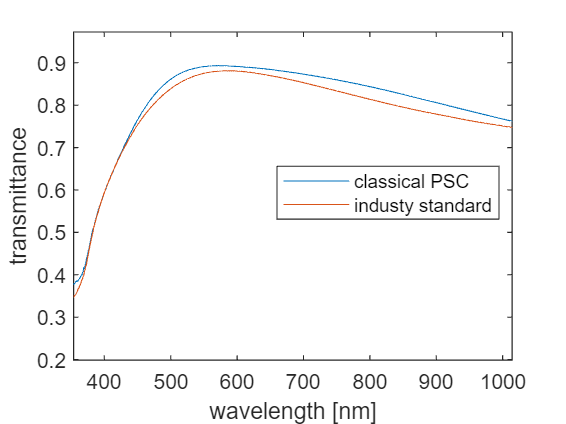

R = data(:, 3); % Reflectance
T = data(:, 2); % Transmittance
A = data(:, 1); % Absorbance
% -------------------------------------------------------------------------
% PSC with AZO and EVA on PV (Using Optimized Bragg Layer Thicknesses)
% -------------------------------------------------------------------------
dPSC = [dBragg_optimized_side1, dgls, dBragg_optimized_side2];
materials = ["air",matPSC,"SiO2_Fraunhofer","air","const=2.4254","mSi"];
stack = set_stack(materials, [dPSC, dAZO, dair, dARC], lam, theta, incoh);
[~, T_PSC_AZO_air_PV, ~] = ATR1D(stack);
Jsc_PSC_AZO_air_PV = get_electric(lam, T_PSC_AZO_air_PV.sp).jsc;
%[A1,T1,R1] = ATR1D(stack);
figure();
plot(lam, T_PSC_AZO_air_PV.sp, lam, T_DSM_air_PV);
xlabel('wavelength [nm]'); ylabel('transmittance');
xlim([lam(1) 1030]); ylim([0 1]);
xticks([400 500 600 700 800 900 1000]);
%xticks([400,500,6000,700,800,900,1000]);
yticks([0.1,0.2,0.3,0.4,0.5,0.6,0.7,0.8,0.9,1.0]);
legend('classical PSC','industy standard')

sample_number = 1:length(R);
load("DSM.mat");

PSC_lam = interp1(DSM(:,1), DSM(:,2), lam, 'spline')';
T_PSC_PV = T_PSC_AZO_air_PV.sp .* PSC_lam;

[A1,T1,R1] = ATR1D(stack);

%Manually plugged out values
PSC_VOC = get_electric(lam,T_PSC_AZO_air_PV.sp).Voc;
PSC_JSC=get_electric(lam,T_PSC_AZO_air_PV.sp).jsc;
PSC_Pmax=get_electric(lam,T_PSC_AZO_air_PV.sp).Pmax;
%END OF MANUAL
disp(['Jsc for DSM standard: ' num2str(Jsc_DSM_air_PV)]);

Jsc for DSM standard: 30.8838


disp(['Jsc for classical PSC: ' num2str(Jsc_PSC_AZO_air_PV)]);

Jsc for classical PSC: 32.3182


disp(['Gain in Jsc: ' num2str(((Jsc_PSC_AZO_air_PV/Jsc_DSM_air_PV)-1)*100) '%']);

Gain in Jsc: 4.6446%


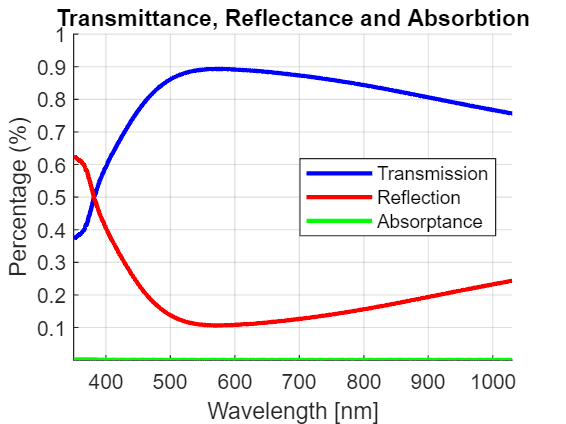



figure;
hold on;
plot(lam, T1.s, 'b', 'LineWidth', 2, 'DisplayName', 'Transmission');
plot(lam, R1.s, 'r', 'LineWidth', 2, 'DisplayName', 'Reflection');
plot(lam, A1.s, 'g', 'LineWidth', 2, 'DisplayName', 'Absorptance');
title('Transmittance, Reflectance and Absorbtion');
xlabel('Wavelength [nm]');
ylabel('Percentage (%)');
legend('show','Location','east');
xlim([lam(1) 1030]);
xticks([400 500 600 700 800 900 1000]);
ylim([0 1]);
yticks([0.1,0.2,0.3,0.4,0.5,0.6,0.7,0.8,0.9,1.0])
grid on;
set(gcf, 'Color', 'w');
hold off;

% -------------------------------------------------------------------------
% FUNCTION DEFINITION
% -------------------------------------------------------------------------



function Jsc = calculateJsc(x)
lam = linspace(350, 1200, 851);
dgls = 2e6; dair = 2e6; dair = 2e6; dAZO = 5; dARC = 61.8;
Bragg = repmat(["SiO2_Fraunhofer", "ZrO2_Fraunhofer"],1,4);
Bragg2 = repmat(["ZrO2_Fraunhofer", "SiO2_Fraunhofer"],1,1);
matPSC = [Bragg,"plain",Bragg2];
incoh = 1e3; % incoherent layer is 1000nm thickness
theta = 0;
% Split x into two parts to create an asymmetric structure
dBragg_side1 = x(1:8); % First half for one side
dBragg_side2 = x(9:end); % Second half for the other side
% Create the asymmetric layer structure
dPSC = [dBragg_side1, dgls, dBragg_side2];
materials = ["air",matPSC,"SiO2_Fraunhofer","air","const=2.4254","mSi"];
stack = set_stack(materials, [dPSC, dAZO, dair, dARC], lam, theta, incoh);
[~, T_PSC_AZO_air_PV, ~] = ATR1D(stack);
Jsc_PSC_AZO_air_PV = get_electric(lam, T_PSC_AZO_air_PV.sp).jsc;


Jsc = -Jsc_PSC_AZO_air_PV;
end
% -------------------------------------------------------------------------


